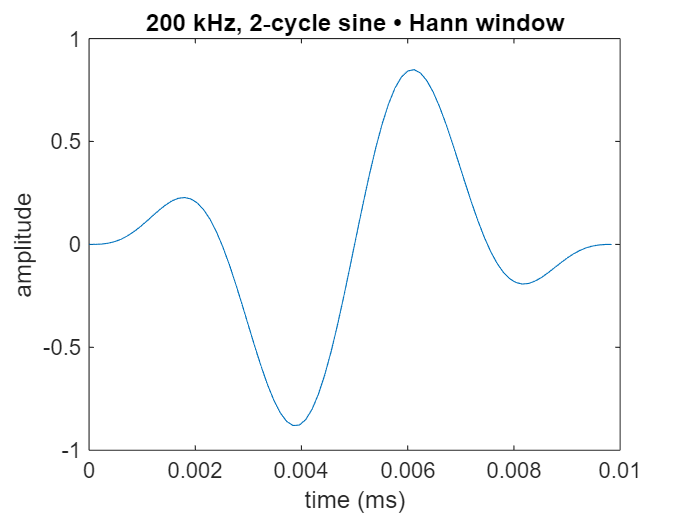

%% 1) MATERIAL PROPERTIES & WAVE SPEEDS
% Young's modulus [Pa] and density [kg/m^3]
E_al = 69e9;   rho_al = 2700;
E_cu = 110e9;  rho_cu = 8960;
E_st = 210e9;  rho_st = 7850;

c_al = sqrt(E_al/rho_al);   % ~5059 m/s
c_cu = sqrt(E_cu/rho_cu);   % ~3507 m/s
c_st = sqrt(E_st/rho_st);   % ~5150 m/s

%% 2) GEOMETRY & GRID
L     = 0.5;    % total rod length [m]
dx    = 1e-3;      % spatial step [m]
x     = (0:dx:L)'; % column vector
Nx    = length(x);

% % Assign c(x) piecewise: 0–100 mm Al, 100–200 mm Cu, 200–300 mm Steel
c_vec = zeros(Nx,1);
% c_vec(x<=100e-3)            = c_al;
% c_vec(x>100e-3 & x<=200e-3) = c_cu;
% c_vec(x>200e-3)             = c_st;
c_vec(:)=c_al;
%% 3) TIME GRID
dt    = 0.12e-6;        % time step [s]
Tend  = 150e-6;         % total time [s]  
t     = 0:dt:Tend;      % row vector
Nt    = length(t);

% CFL check
rmax = max(c_vec)*dt/dx;
if rmax>=1
  error('CFL violated: max(c)*dt/dx = %.3f >= 1. Reduce dt or increase dx.',rmax);
end

%% 4) SOURCE SIGNAL @ x_src = 150 mm
fc      = 200e3;    % 200 kHz
ncycle  = 2;
Tsig    = ncycle/fc;
Ns      = round(Tsig/dt);
ts      = (0:Ns-1)*dt;
src_sig = sin(2*pi*fc*ts) .* hann(Ns)';  % 2-cycle sine * Hann
% plot to check
figure;
% subplot(2,1,1)
plot(ts*1e3, src_sig)
xlabel('time (ms)')
ylabel('amplitude')
title('200 kHz, 2‐cycle sine • Hann window')

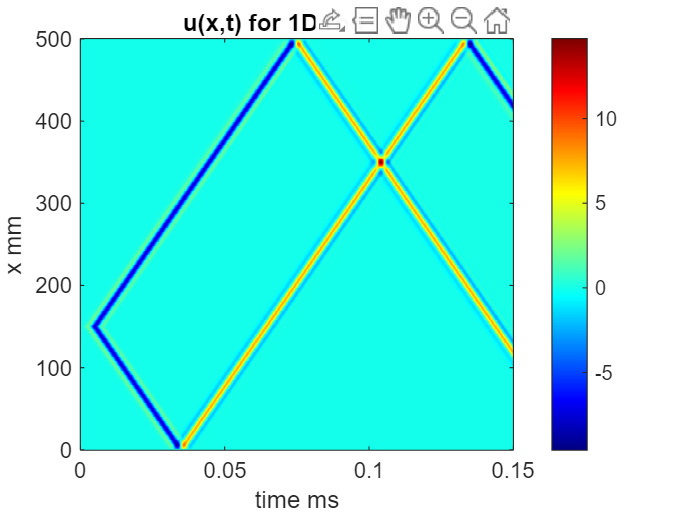


% zero‐pad to length Nt
src = zeros(1,Nt);
src(1:Ns) = src_sig;

% find source index
%find the grid‐point in x that is nearest to 
% the physical source location of 150 mm, and call its index i_src
[~, i_src] = min(abs(x - 150e-3)); 

%% 5) ALLOCATE & INITIAL CONDITIONS
u      = zeros(Nx, Nt);  % displacement
% u(:,1) = 0 by default
% u(:,2) = 0 by default (zero initial velocity)

%% 6) TIME‐MARCH (central‐difference explicit)
for n = 2:Nt-1
  % interior points
  for i = 2:Nx-1
    cfl2 = (c_vec(i)*dt/dx)^2;
    u(i,n+1) = 2*u(i,n) - u(i,n-1) ...
               + cfl2*( u(i+1,n) - 2*u(i,n) + u(i-1,n) );
  end
  % Dirichlet BCs (fixed ends)
  u(1,n+1)   = 0;
  u(Nx,n+1)  = 0;
  % inject source (additive)
  % u(i_src,n) = u(i_src,n) + src(n);
  u(i_src,n+1) = u(i_src,n+1) + src(n);

end

%% 7) PLOT SPATIO‐TEMPORAL WAVEFIELD
figure(1); clf;
imagesc(t*1e3, x*1e3, u);
axis xy; colormap jet; colorbar;
xlabel('time ms'); ylabel('x mm');
title('u(x,t) for 1D rod (Al)');


%% 8) ESTIMATE WAVE SPEED
% pick two positions, e.g. x1=50 mm, x2=250 mm
x1 = 50e-3;  x2 = 250e-3;
[~, i1] = min(abs(x-x1));
[~, i2] = min(abs(x-x2));

% find first crossing above threshold
th = 0.05*max(abs(u(:)));  % 5% of global max
n1 = find(abs(u(i1,:))>th,1);
n2 = find(abs(u(i2,:))>th,1);

t1 = (n1-1)*dt;
t2 = (n2-1)*dt;
v_est = (x2-x1)/(t2-t1);

fprintf('Arrival at x=%.1f mm: t1=%.2f µs\n',x1*1e3, t1*1e6);

Arrival at x=50.0 mm: t1=21.36 µs


fprintf('Arrival at x=%.1f mm: t2=%.2f µs\n',x2*1e3, t2*1e6);

Arrival at x=250.0 mm: t2=21.36 µs


fprintf('Estimated speed: v = %.1f m/s\n', v_est);

Estimated speed: v = Inf m/s



% Compare to local c in that segment
if x2<=100e-3
  c_theor = c_al;
elseif x1>=100e-3 && x2<=200e-3
  c_theor = c_cu;
else
  c_theor = c_st;
end
fprintf('Theoretical c ≈ %.1f m/s\n', c_theor);

Theoretical c ≈ 5172.2 m/s


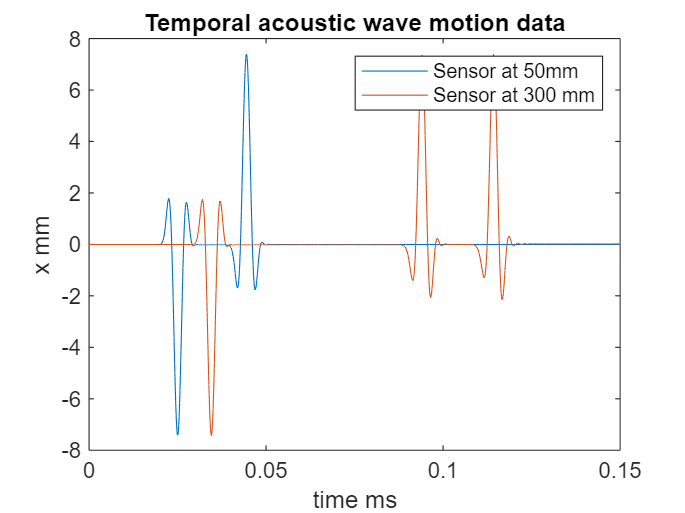

plot(t*1e3,u(50,:));hold on;
plot(t*1e3,u(300,:));hold off;
xlabel('time ms'); ylabel('x mm');
title('Temporal acoustic wave motion data');
legend('Sensor at 50mm','Sensor at 300 mm');